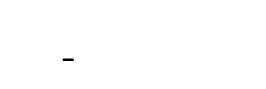

错误使用 annotation
位置值必须介于 0 与 1 之间。

%% 能级和跃迁示意图 - 双面板图
% 清除工作区并关闭所有图形
clear all;
close all;

%% 创建图形窗口
f1 = figure('Position', [100, 100, 1200, 400], 'Color', 'w');


%% 左子图 - 171Yb (I=1/2, 2个子能级)
f11 = subplot(1,2,1);
hold on;
box off; axis off;
xlim([-2 2]);
ylim([0 3]);

% 设置能级参数
llen = 0.25;
glevel = [-1/2:+1/2];
elevel = [-3/2:+3/2];
gy = 0.5;
ey = 2.5;
boxx = 0.5; 
boxy = 0.3;

for k = 1:length(glevel)
    plot([glevel(k)-llen glevel(k)+llen],[gy gy],...
        '-','Color','k','LineWidth',1.6);
    annotation(f1,'textbox',...
    [glevel(k)-boxx/2 gy-boxy boxx boxy],...
    'String',[num2str(2*glevel(k),'%.0f'),'/2'],...
    'FontWeight','normal',...
    'FontSize',20,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');
end


for k = 1:length(elevel)
    plot([elevel(k)-llen elevel(k)+llen],[ey ey],...
        '-','Color','k','LineWidth',1.6);
    annotation(f11,'textbox',...
    [elevel(k)-boxx/2 ey boxx boxy],...
    'String',[num2str(2*elevel(k),'%.0f'),'/2'],...
    'FontWeight','normal',...
    'FontSize',20,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');
end


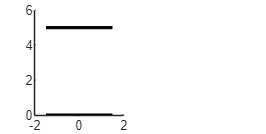


% 子能级数量
num_sublevels = 2;

% 计算子能级位置
sublevel_spacing = 1.5;
sublevel_positions = linspace(-sublevel_spacing*(num_sublevels-1)/2, ...
                               sublevel_spacing*(num_sublevels-1)/2, num_sublevels);


% 绘制能级线
line([-sublevel_spacing*num_sublevels/2, sublevel_spacing*num_sublevels/2], ...
     [ground_level, ground_level], 'Color', 'k', 'LineWidth', 2);
line([-sublevel_spacing*num_sublevels/2, sublevel_spacing*num_sublevels/2], ...
     [excited_level, excited_level], 'Color', 'k', 'LineWidth', 2);

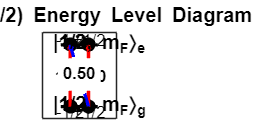


% 绘制子能级点
for k = 1:num_sublevels
    plot(sublevel_positions(k), ground_level, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 8);
    plot(sublevel_positions(k), excited_level, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 8);
end

% Clebsch-Gordan系数的平方 (示例值)
cg_squares_171 = [1.00, 1.00];  % 假设两个跃迁强度相同

% 绘制实线箭头1 (循环跃迁: m_F = +1/2 到 +1/2)
from_sublevel = 2; to_sublevel = 2;
x1 = sublevel_positions(from_sublevel); y1 = ground_level;
x2 = sublevel_positions(to_sublevel); y2 = excited_level;
plot([x1, x2], [y1, y2], 'r-', 'LineWidth', 2);
dx = x2 - x1; dy = y2 - y1;
angle = atan2(dy, dx);
head_length = 0.3; head_width = 0.2;
x_head = x2 - head_length * cos(angle);
y_head = y2 - head_length * sin(angle);
patch([x2, x_head + head_width * sin(angle), x_head - head_width * sin(angle)], ...
      [y2, y_head - head_width * cos(angle), y_head + head_width * cos(angle)], ...
      'r', 'EdgeColor', 'r', 'FaceColor', 'r');
text((x1+x2)/2+0.1, (y1+y2)/2, sprintf('%.2f', cg_squares_171(1)), ...
     'FontSize', 10, 'FontWeight', 'bold', 'HorizontalAlignment', 'center', 'BackgroundColor', 'w');

% 绘制实线箭头2 (循环跃迁: m_F = -1/2 到 -1/2)
from_sublevel = 1; to_sublevel = 1;
x1 = sublevel_positions(from_sublevel); y1 = ground_level;
x2 = sublevel_positions(to_sublevel); y2 = excited_level;
plot([x1, x2], [y1, y2], 'r-', 'LineWidth', 2);
dx = x2 - x1; dy = y2 - y1;
angle = atan2(dy, dx);
head_length = 0.3; head_width = 0.2;
x_head = x2 - head_length * cos(angle);
y_head = y2 - head_length * sin(angle);
patch([x2, x_head + head_width * sin(angle), x_head - head_width * sin(angle)], ...
      [y2, y_head - head_width * cos(angle), y_head + head_width * cos(angle)], ...
      'r', 'EdgeColor', 'r', 'FaceColor', 'r');
text((x1+x2)/2+0.1, (y1+y2)/2, sprintf('%.2f', cg_squares_171(2)), ...
     'FontSize', 10, 'FontWeight', 'bold', 'HorizontalAlignment', 'center', 'BackgroundColor', 'w');

% 绘制虚线箭头 (自旋翻转跃迁: m_F = +1/2 到 -1/2)
from_sublevel = 2; to_sublevel = 1;
x1 = sublevel_positions(from_sublevel); y1 = ground_level;
x2 = sublevel_positions(to_sublevel); y2 = excited_level;
plot([x1, x2], [y1, y2], 'b--', 'LineWidth', 2);
dx = x2 - x1; dy = y2 - y1;
angle = atan2(dy, dx);
head_length = 0.3; head_width = 0.2;
x_head = x2 - head_length * cos(angle);
y_head = y2 - head_length * sin(angle);
patch([x2, x_head + head_width * sin(angle), x_head - head_width * sin(angle)], ...
      [y2, y_head - head_width * cos(angle), y_head + head_width * cos(angle)], ...
      'b', 'EdgeColor', 'b', 'FaceColor', 'b');
text((x1+x2)/2, (y1+y2)/2+0.2, sprintf('%.2f', 0.5), ...
     'FontSize', 10, 'FontWeight', 'bold', 'HorizontalAlignment', 'center', 'BackgroundColor', 'w');

% 添加能级标签
text(-sublevel_spacing*num_sublevels/2 - 0.8, ground_level, ...
     '|1/2, m_F\rangle_g', 'FontSize', 12, 'FontWeight', 'bold');
text(-sublevel_spacing*num_sublevels/2 - 0.8, excited_level, ...
     '|1/2, m_F\rangle_e', 'FontSize', 12, 'FontWeight', 'bold');

% 添加子能级标签
mf_labels_171 = {'-1/2', '+1/2'};
for i = 1:num_sublevels
    text(sublevel_positions(i), ground_level-0.4, mf_labels_171{i}, ...
         'HorizontalAlignment', 'center', 'FontSize', 10);
    text(sublevel_positions(i), excited_level+0.4, mf_labels_171{i}, ...
         'HorizontalAlignment', 'center', 'FontSize', 10);
end

% 设置右子图属性
axis equal;
xlim([-sublevel_spacing*num_sublevels/2 - 1.5, sublevel_spacing*num_sublevels/2 + 1.5]);
ylim([-1, excited_level + 1]);
set(gca, 'YTick', []);
set(gca, 'XTick', []);
box on;
grid off;
title('^{171}Yb (I=1/2) Energy Level Diagram', 'FontSize', 12, 'FontWeight', 'bold');

% 添加图例
h1 = plot(NaN, NaN, 'r-', 'LineWidth', 2);
h2 = plot(NaN, NaN, 'b--', 'LineWidth', 2);

hold off;

%% 添加整体标题
%sgtitle('Energy Level Diagrams with Transition Strengths', 'FontSize', 14, 'FontWeight', 'bold');

%% 添加整体图注
annotation('textbox', [0.3, 0.01, 0.4, 0.04], ...
           'String', 'Note: Numbers next to arrows denote squared Clebsch-Gordan coefficients', ...
           'FontSize', 10, 'EdgeColor', 'none', 'HorizontalAlignment', 'center', 'FontWeight', 'bold');

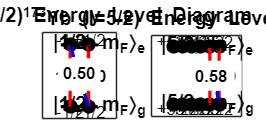


%% 右子图 - 173Yb (I=5/2, 6个子能级)
subplot(1,2,2);
hold on;

% 设置能级参数
ground_level = 0;  % 基态能级
excited_level = 5; % 激发态能级

% 子能级数量
num_sublevels = 6;

% 计算子能级位置
sublevel_spacing = 0.8;
sublevel_positions = linspace(-sublevel_spacing*(num_sublevels-1)/2, ...
                               sublevel_spacing*(num_sublevels-1)/2, num_sublevels);

% 绘制能级线
line([-sublevel_spacing*num_sublevels/2, sublevel_spacing*num_sublevels/2], ...
     [ground_level, ground_level], 'Color', 'k', 'LineWidth', 2);
line([-sublevel_spacing*num_sublevels/2, sublevel_spacing*num_sublevels/2], ...
     [excited_level, excited_level], 'Color', 'k', 'LineWidth', 2);

% 绘制子能级点
for i = 1:num_sublevels
    plot(sublevel_positions(i), ground_level, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 8);
    plot(sublevel_positions(i), excited_level, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 8);
end

% Clebsch-Gordan系数的平方
cg_squares = [1.00, 0.58, 0.31, 0.16, 0.08, 0.03];

% 绘制实线箭头1 (循环跃迁: m_F = +5/2 到 +5/2)
from_sublevel = 6; to_sublevel = 6;
x1 = sublevel_positions(from_sublevel); y1 = ground_level;
x2 = sublevel_positions(to_sublevel); y2 = excited_level;
plot([x1, x2], [y1, y2], 'r-', 'LineWidth', 2);
dx = x2 - x1; dy = y2 - y1;
angle = atan2(dy, dx);
head_length = 0.3; head_width = 0.2;
x_head = x2 - head_length * cos(angle);
y_head = y2 - head_length * sin(angle);
patch([x2, x_head + head_width * sin(angle), x_head - head_width * sin(angle)], ...
      [y2, y_head - head_width * cos(angle), y_head + head_width * cos(angle)], ...
      'r', 'EdgeColor', 'r', 'FaceColor', 'r');
text((x1+x2)/2+0.1, (y1+y2)/2, sprintf('%.2f', cg_squares(1)), ...
     'FontSize', 10, 'FontWeight', 'bold', 'HorizontalAlignment', 'center', 'BackgroundColor', 'w');

% 绘制虚线箭头1 (自旋翻转跃迁: m_F = +5/2 到 +3/2)
from_sublevel = 6; to_sublevel = 5;
x1 = sublevel_positions(from_sublevel); y1 = ground_level;
x2 = sublevel_positions(to_sublevel); y2 = excited_level;
plot([x1, x2], [y1, y2], 'b--', 'LineWidth', 2);
dx = x2 - x1; dy = y2 - y1;
angle = atan2(dy, dx);
head_length = 0.3; head_width = 0.2;
x_head = x2 - head_length * cos(angle);
y_head = y2 - head_length * sin(angle);
patch([x2, x_head + head_width * sin(angle), x_head - head_width * sin(angle)], ...
      [y2, y_head - head_width * cos(angle), y_head + head_width * cos(angle)], ...
      'b', 'EdgeColor', 'b', 'FaceColor', 'b');
text((x1+x2)/2-0.1, (y1+y2)/2, sprintf('%.2f', cg_squares(2)), ...
     'FontSize', 10, 'FontWeight', 'bold', 'HorizontalAlignment', 'center', 'BackgroundColor', 'w');

% 绘制实线箭头2 (循环跃迁: m_F = +3/2 到 +3/2)
from_sublevel = 5; to_sublevel = 5;
x1 = sublevel_positions(from_sublevel); y1 = ground_level;
x2 = sublevel_positions(to_sublevel); y2 = excited_level;
plot([x1, x2], [y1, y2], 'r-', 'LineWidth', 2);
dx = x2 - x1; dy = y2 - y1;
angle = atan2(dy, dx);
head_length = 0.3; head_width = 0.2;
x_head = x2 - head_length * cos(angle);
y_head = y2 - head_length * sin(angle);
patch([x2, x_head + head_width * sin(angle), x_head - head_width * sin(angle)], ...
      [y2, y_head - head_width * cos(angle), y_head + head_width * cos(angle)], ...
      'r', 'EdgeColor', 'r', 'FaceColor', 'r');
text((x1+x2)/2+0.1, (y1+y2)/2, sprintf('%.2f', cg_squares(2)), ...
     'FontSize', 10, 'FontWeight', 'bold', 'HorizontalAlignment', 'center', 'BackgroundColor', 'w');

% 添加能级标签
text(-sublevel_spacing*num_sublevels/2 - 0.8, ground_level, ...
     '|5/2, m_F\rangle_g', 'FontSize', 12, 'FontWeight', 'bold');
text(-sublevel_spacing*num_sublevels/2 - 0.8, excited_level, ...
     '|5/2, m_F\rangle_e', 'FontSize', 12, 'FontWeight', 'bold');

% 添加子能级标签
mf_labels = {'+5/2', '+3/2', '+1/2', '-1/2', '-3/2', '-5/2'};
for i = 1:num_sublevels
    text(sublevel_positions(i), ground_level-0.4, mf_labels{i}, ...
         'HorizontalAlignment', 'center', 'FontSize', 10);
    text(sublevel_positions(i), excited_level+0.4, mf_labels{i}, ...
         'HorizontalAlignment', 'center', 'FontSize', 10);
end

% 设置左子图属性
axis equal;
xlim([-sublevel_spacing*num_sublevels/2 - 1.5, sublevel_spacing*num_sublevels/2 + 1.5]);
ylim([-1, excited_level + 1]);
set(gca, 'YTick', []);
set(gca, 'XTick', []);
box on;
grid off;
title('^{173}Yb (I=5/2) Energy Level Diagram', 'FontSize', 12, 'FontWeight', 'bold');

% 添加图例
h1 = plot(NaN, NaN, 'r-', 'LineWidth', 2);
h2 = plot(NaN, NaN, 'b--', 'LineWidth', 2);

hold off;

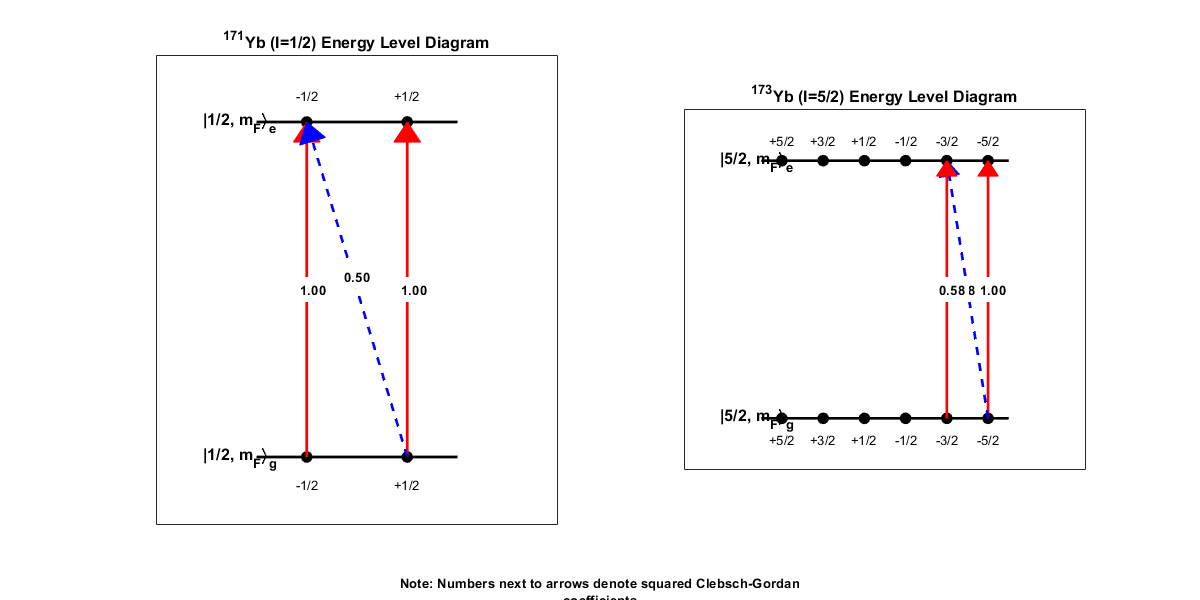


set(f1,'Visible','on');